# PAH Lift Surface Gradients

clear; clc; close;

## Initialize User Deined Parameters

% Define airfoils of extreme cases full rigidity no aleviation and maximum
% camber. 
%   Currently I will be assuming a linear interpolation between the
%   extreme cases of airfoil deflection.
%   TODO: incorporate negative camber

%load files
fileName_maxCamber= "Selig 1223"; % filename of airfoil with the maximum camber
fileName_neutralCamber = "KL_sexy_sexy"; % filename of airfoil with the neutral camber

% ploting paramters
nPlotPoints_linearRegion = 10; % number of plot points in the linear region
nPlotPoints_NLPreStall = 5; % number of plot points in the Nonlinear prestall Region
nPlotPoints_NLPostStall = 2; % number of plot points in the Nonlinear poststall Region

% number of intermediate airfoils to produce
n_InermediateCambers = 10;

% cambers
camber_neutral = .03767;
camber_max = .81;

% plot slice parameters
nSlicePoints = 100;

% colour oder for plots
startColour = [1,0,1]; % magenta
endColour = [0,1,1]; % cyan

% numver of frames to animate 
n_frames_animate = 100;
n_frames_plot = 5;
n_frames_animate = 10; % use this line for fast running code

% slice colours
slice_colours = [.5,.5,0; 0,.5,0; 0,0,.5]

slice_colours =     0.5000    0.5000         0
         0    0.5000         0
         0         0    0.5000


## Initialize Variables

% Load airfoils
airfoil_maxCamber = ReadAirfoil(fileName_maxCamber);
airfoil_neutralCamber = ReadAirfoil(fileName_neutralCamber);

% store the plot points as an array
n_plotPoints_liftCurve = [nPlotPoints_linearRegion, nPlotPoints_NLPreStall, nPlotPoints_NLPostStall];

n_alphaPoints_liftCurve = sum(n_plotPoints_liftCurve);

% number of colours required for plotting
n_Colours = n_InermediateCambers + 2; % intermediate cambers + boundery cambers

## Plot Airoils

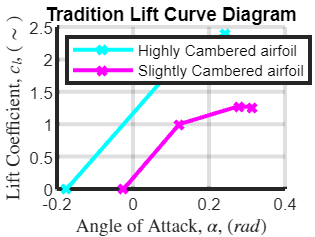

% get the points to plot
[alphas_maxCamber, c_ls_maxCamber] = airfoil_maxCamber.getPlotPoints;
[alphas_neutralCamber, c_ls_neutralCamber] = airfoil_neutralCamber.getPlotPoints;

% produce the traditional superimposed plot
figure;
hold on
plot(alphas_maxCamber, c_ls_maxCamber,"c-x","LineWidth",2, "DisplayName","Highly Cambered airfoil");
plot(alphas_neutralCamber, c_ls_neutralCamber,"m-x", "LineWidth",2, "DisplayName","Slightly Cambered airfoil");
title("Tradition Lift Curve Diagram");
xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");
legend("Location","northwest");
set(gca,"LineWidth", 2);
grid on;


% do the same thing again but with more points

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   Mesh Lift Curves    %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pereimter curves
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%  Mesh Alphas  %%%%%%%%%%%%%%%%%
%prepare loop variables
regionIndex = 1;
alphas_maxCamber_interped = zeros(n_alphaPoints_liftCurve,1);
alphas_neutralCamber_interped = zeros(n_alphaPoints_liftCurve,1);
c_ls_maxCamber_interped = zeros(n_alphaPoints_liftCurve,1);
c_ls_neutralCamber_interped = zeros(n_alphaPoints_liftCurve,1);

% Note I am possibly currently duplicating point on segment transitions but is isn't
% currently affecting 
alphas_maxCamber_interped(1) = alphas_maxCamber(1);
alphas_neutralCamber_interped(1) = alphas_neutralCamber(1);
for i = 1:3
    % n_plotPoints_region = n_plotPoints_liftCurve(i);
    % % linterp alphas
    % alphas_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_maxCamber(i), alphas_maxCamber(i+1), n_plotPoints_region);
    % alphas_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_neutralCamber(i), alphas_neutralCamber(i+1), n_plotPoints_region);
    % %linterp cl's
    % c_ls_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(c_ls_maxCamber(i), c_ls_maxCamber(i+1), n_plotPoints_region);
    % c_ls_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(c_ls_neutralCamber(i), c_ls_neutralCamber(i+1), n_plotPoints_region);
    % % update index og access into array
    % regionIndex = regionIndex + n_plotPoints_region;
        n_plotPoints_region = n_plotPoints_liftCurve(i); % determine number of alpha in this mesh segment

    % linterp alphas
    alphas_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_maxCamber(i), alphas_maxCamber(i+1), n_plotPoints_region);
    alphas_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_neutralCamber(i), alphas_neutralCamber(i+1), n_plotPoints_region);

    alph_mc = linspace(alphas_maxCamber(i), alphas_maxCamber(i+1), n_plotPoints_region+1);
    alph_nc = linspace(alphas_neutralCamber(i), alphas_neutralCamber(i+1), n_plotPoints_region+1);
    
    

    alphas_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = alph_mc(2:end);
    alphas_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = alph_nc(2:end);
    
    % linterp cl's
    c_ls_mc = linspace(c_ls_maxCamber(i), c_ls_maxCamber(i+1), n_plotPoints_region+1);
    c_ls_nc = linspace(c_ls_neutralCamber(i), c_ls_neutralCamber(i+1), n_plotPoints_region+1);

    % produce the smoothed cl's
    spl_MC = CL_alpha_Smooother([alphas_maxCamber', c_ls_maxCamber'], 0, 2);
    c_ls_mc = fnval(spl_MC,alph_mc);
    spl_NC = CL_alpha_Smooother([alphas_neutralCamber', c_ls_neutralCamber'], 0, 2);
    c_ls_nc = fnval(spl_NC,alph_nc);


    c_ls_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = c_ls_mc(2:end);
    c_ls_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = c_ls_nc(2:end);

    % update index of access into array
    regionIndex = regionIndex + n_plotPoints_region;
end

% plot the edge meshed curves
figure;
hold on
plot(alphas_maxCamber_interped, c_ls_maxCamber_interped,"c-x","LineWidth",2, "DisplayName","Highly Cambered airfoil");
plot(alphas_neutralCamber_interped, c_ls_neutralCamber_interped,"m-x", "LineWidth",2, "DisplayName","Slightly Cambered airfoil");

xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");

%legend(get(gca,'Children'), ["Highly Cambered airfoil","Slightly Cambered airfoil"], "Location","northwest");
PerimeterCurves = get(gca,'Children')

PerimeterCurves =   2×1 Line array:

  Line    (Slightly Cambered airfoil)
  Line    (Highly Cambered airfoil)


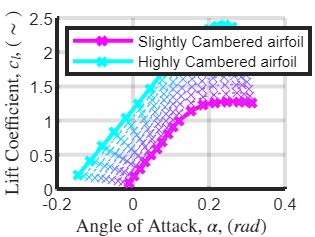


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Interior Curves
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% camber index will be defined with 0 being the camber of neutrally camber
% airfoil and nCIntermediateCamber being the index of the maximum camber
% airfoil.

% alpha index will be defined with 0 being the zero lift alpha (alpha_0)
% and n_alphaPoints_liftCurve being the index of alpha_post_stall

%   alpha             =   Lift_surface_mesh(alphaIndex, camberIndex, 1)
%   camberParameter   =   Lift_surface_mesh(alphaIndex, camberIndex, 2)
%   C_L               =   Lift_surface_mesh(alphaIndex, camberIndex, 3)


for alpha_index = 1:n_alphaPoints_liftCurve
    % interpolate from one curve to the opposing one
    alpha_coords(alpha_index,:) = linspace(alphas_neutralCamber_interped(alpha_index), alphas_maxCamber_interped(alpha_index), n_InermediateCambers);
    camber_coords(alpha_index,:) = linspace(camber_neutral, camber_max, n_InermediateCambers);
    cl_coords(alpha_index,:) = linspace(c_ls_neutralCamber_interped(alpha_index), c_ls_maxCamber_interped(alpha_index), n_InermediateCambers);
    % store the points in the array
end

Lift_surface_mesh(:,:,1) = alpha_coords;
Lift_surface_mesh(:,:,2) = camber_coords;
Lift_surface_mesh(:,:,3) = cl_coords;
plot(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,3),":x");
% format plot
set(gca,"LineWidth", 2);
grid on;

% now add the legened
legend(PerimeterCurves, "Location","northwest");


% set up colour order for plot
colourArray = zeros(n_Colours,3); % initalize array to hold colour order
for i = 1:3 % interpolate colours for colour array
    colourArray(:,i) = linspace(startColour(i), endColour(i), n_Colours);
end

% apply the colour order
colororder(colourArray);

## produce a plot of cl vs camber

% plot the edge meshed curves
figure;
hold on

% plot the edges
plot(Lift_surface_mesh(1,:,2), Lift_surface_mesh(1,:,3),"m-x","LineWidth",3, "DisplayName","small AoA")
plot(Lift_surface_mesh(end,:,2), Lift_surface_mesh(end,:,3),"c-x", "LineWidth",3, "DisplayName","Large AoA")
PerimeterCurves = get(gca,'Children'); % store the curves on the perimiter to add to legend

% plot the spectrum
% for i = 1:size(Lift_surface_mesh, 1)
%     plot(Lift_surface_mesh(:,i,2), Lift_surface_mesh(:,i,3),":x", "Color",colourArray(i,:));
% end
n_Colours = size(Lift_surface_mesh,1)

n_Colours = 17

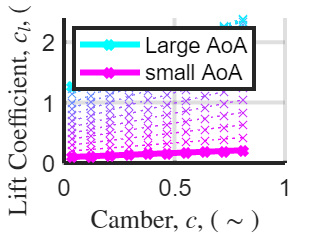

colourArray = zeros(n_Colours,3); % initalize array to hold colour order
for i = 1:3 % interpolate colours for colour array
    colourArray(:,i) = linspace(startColour(i), endColour(i), n_Colours);
end

for i = 1:17
    plot(Lift_surface_mesh(i,:,2), Lift_surface_mesh(i,:,3),":x", "Color",colourArray(i,:));
end

xlabel("Camber, $c$, ($\sim$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");
% now add the legened
legend(PerimeterCurves, "Location","northwest");
set(gca, "LineWidth", 2); set(gca, "FontSize", 12);
xlim([min(Lift_surface_mesh(i,:,2)), max(Lift_surface_mesh(i,:,2))])
xlim([round(min(Lift_surface_mesh(i,:,2)),1), round(max(Lift_surface_mesh(i,:,2)),0)])
grid on

## convert from 2D to 3D

% note we are extremely high aspect ratio and tapered to be almost eliptic
% and we have winglets installed thus C_L is aproximately c_l it is 93%
% smaller thus not worth correcting for
C_L_alpha = polhamus(2*pi, 30, deg2rad(-1.6), 1, 0)

C_L_alpha = 5.9603

percentError = C_L_alpha/2*pi

percentError = 9.3624



% aircraft is long couled thus reduce lift coeffcient to acount for tail
% lift
Lift_surface_mesh(:,:,3) = Lift_surface_mesh(:,:,3) / 1.05;

## Produce 3D plots

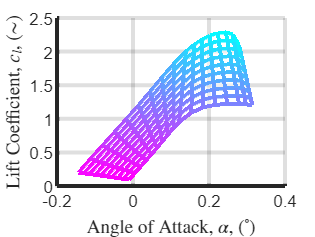

% Load Xfoil lift mesh (comment next to lines out to geet linearized verion
%load('liftMesh_Xfoil.mat');
%Lift_surface_mesh = LiftMesh;

% see through wire frame presented looking like its 2D
figure;
s = mesh(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "LineWidth",2);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); %colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
view([0,0]);
set(gca,"LineWidth", 2);

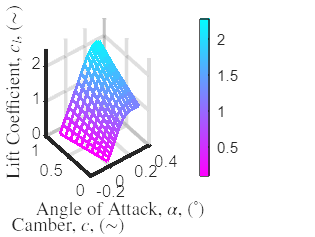


% see through wire frame presented to look like 3D
figure;
s = mesh(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "LineWidth",1.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);

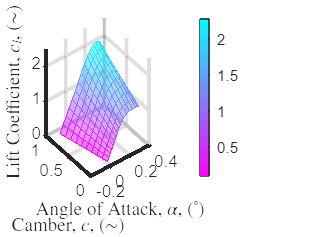


% see Colourful wire frame
figure;
s = mesh(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")

%s.FaceColor = 'flat'; % colour the segments
s.FaceColor = 'interp'; % colour the segments
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);

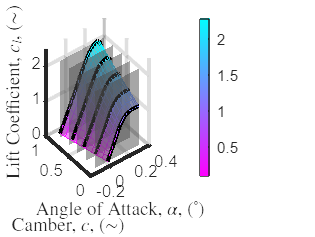



% C_L slice will remain unchanged
C_L_space = linspace(min(Lift_surface_mesh(:,:,3),[],"all"), max(Lift_surface_mesh(:,:,3),[],"all"), nSlicePoints);

% these will change
camber_max = max(Lift_surface_mesh(:,:,2),[],"all");
camber_min = min(Lift_surface_mesh(:,:,2),[],"all");
alpha_max = max(Lift_surface_mesh(:,:,1),[],"all");
alpha_min = min(Lift_surface_mesh(:,:,1),[],"all");


[alpha_slice, C_L_slice] = meshgrid(linspace(alpha_min, alpha_max, nSlicePoints), C_L_space);
camber_slice = camber_max - (camber_max - camber_min) / (alpha_max-alpha_min) * (alpha_slice - alpha_min);
%slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor","m");


% surface
camber_min_plot = .3676;
camber_max_plot = .3676;

% static rendering
figure;
for camber = linspace(camber_neutral, camber_max, n_frames_plot)
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "FaceColor","interp", "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    
    camber_slice = ones(size(alpha_slice)) * camber;
    hold on;
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

    drawnow;

end

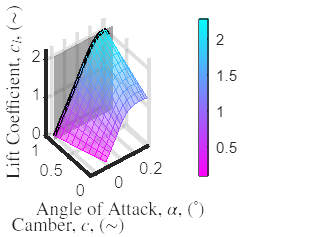


% animation
figure;
for camber = linspace(camber_neutral, camber_max, n_frames_animate)
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "FaceColor","interp", "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    %xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    
    camber_slice = ones(size(alpha_slice)) * camber;
    hold on;
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    

    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

    % update the plot
    drawnow;
    hold off; % turn off hold so as to remove the old plane
end

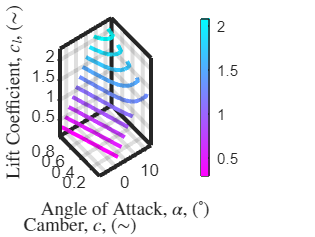



% Plot the 3d contour plot with level curves of lift
contour3(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3),10, "LineWidth",2);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); colorbar;
%xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);

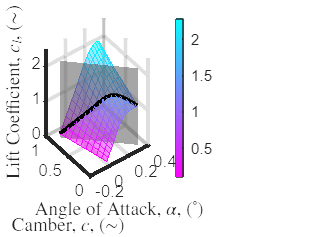

% view([0,90]); % for top view
% Note to self. can plot this with 100 contours at linewidth .5 and then do
% hold on and plot with 10 contours at linewidth 2 to produce a good figure



% surface
figure;
surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);

% show the slices with contourslice? can show sliced of gust q_bar perturbation

% slice plane
% cover all the alphas an cl_s
[alpha_slice, C_L_slice] = meshgrid(linspace(min(Lift_surface_mesh(:,:,1),[],"all"), max(Lift_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Lift_surface_mesh(:,:,3),[],"all"), max(Lift_surface_mesh(:,:,3),[],"all"), nSlicePoints));


camber_max = max(Lift_surface_mesh(:,:,2),[],"all");
camber_min = min(Lift_surface_mesh(:,:,2),[],"all");
alpha_max = max(Lift_surface_mesh(:,:,1),[],"all");
alpha_min = min(Lift_surface_mesh(:,:,1),[],"all");
camber_slice = camber_max - (camber_max - camber_min) / (alpha_max-alpha_min) * (alpha_slice - alpha_min);

% contour clice deosnt work
%contourslice(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice, C_L_slice, camber_slice, 1)
hold on
slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);

% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

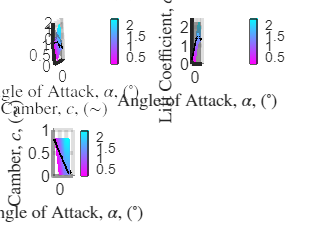


% spoof the subplot figure i want to see
figure;

% trimetric(ish) view
subplot(2,2,1);
surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
view([-12.08 47.25]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

% side view
subplot(2,2,2);
surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "FaceColor",[0.3,0.3,0.3], "EdgeColor","none");
view([0,0]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

% top view
subplot(2,2,3);
surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); colorbar;
xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
view([0,90]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);

## repeat the 3 view for various senarios

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% static plot of various levels of complience
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;

% plotting parameters
camberSlope_max = -.099*57

camberSlope_max = -5.6430

alpha_c = .121; % center or ration of the plane (alpha coordinate
camber_c = camber_neutral; % center or ration of the plane (alpha coordinate
camber_c = (camber_neutral+camber_max)/2; % center or ration of the plane (alpha coordinate

% colours
i=0

i = 0

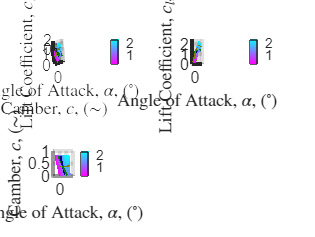

i = 1

sliceColor =     0.5000    0.5000         0


i = 2

sliceColor =          0    0.5000         0


i = 3

sliceColor =          0         0    0.5000


for camber_slope = linspace(0, camberSlope_max, 3)
    i = i+1
    sliceColor = slice_colours(i,:)

    % compute the camber alpha line
    camber_slice = camber_c + (camber_slope) * (alpha_slice - alpha_c);

    %produce the plots

    % trimetric(ish) view
    subplot(2,2,1);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex");
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",.6*sliceColor);
    view([-12.08 47.25]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);

    % side view
    subplot(2,2,2);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    %slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",.3*sliceColor);
    view([0,0]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);

    % top view
    subplot(2,2,3);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    view([0,90]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);

    % update the plot
    drawnow;
end

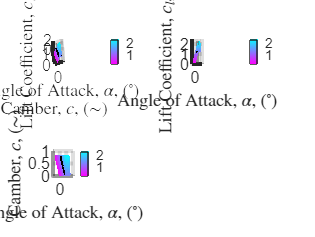


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% animate various levels of complience
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;

for camber_slope = linspace(0, camberSlope_max, n_frames_animate)
    % compute the camber alpha line
    camber_slice = camber_c + (camber_slope) * (alpha_slice - alpha_c);

    %produce the plots

    % trimetric(ish) view
    subplot(2,2,1);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex");
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    view([-12.08 47.25]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
    hold off;

    % side view
    subplot(2,2,2);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    view([0,0]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
    hold off;

    % top view
    subplot(2,2,3);
    surf(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); colorbar;
    xlim([-.2,.4]); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(alpha_slice, camber_slice, C_L_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    view([0,90]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(alpha_intercept(1,:), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
    hold off;

    % update the plot
    drawnow;
end

function [x_intersect, y_intersect, z_intersect] = Mesh_Sheet_Intrsect(X_curve, Y_curve, Z_curve, X_plane, Y_plane, Z_plane, plot_yn)
    % Interpolate the curved mesh onto the grid points of the mesh plane
    Z_interpolated = interp2(X_curve, Y_curve, Z_curve, X_plane, Y_plane);

    % Extract the intersection points
    x_intersect = X_plane(1, :);
    y_intersect = Y_plane(1, :);
    z_intersect = Z_interpolated(1, :);



    if plot_yn
        % Plot the intersection
        figure;
        surf(X_curve, Y_curve, Z_curve); hold on;
        surf(X_plane, Y_plane, Z_plane);

        plot3(x_intersect, y_intersect, z_intersect, 'r-o', LineWidth=3);
        xlabel('X');    ylabel('Y');    zlabel('Z');    [az, el] = view;
        xlims = xlim;   ylims = ylim;   zlims = zlim;

        figure
        plot3(x_intersect, y_intersect, z_intersect, 'r-o', LineWidth=3);
        xlabel('X');    ylabel('Y');    zlabel('Z');    view(az, el);
        xlim(xlims);    ylim(ylims);    zlim(zlims);
    end
end

function spl = CL_alpha_Smooother(four_points_matrix, plot_yn, n)
%   Example:
%       points = [-.174533, 0; .1396, 2.1; .2443, 2.4; .2793, 2.2];
%       spl = generate_spline(points, true);
%       n between 1 and 5, 5 being most linear in linear region (adds spline points on line to force the function)

x_data = four_points_matrix(:,1)';
y_data = four_points_matrix(:,2)';

slope_at_point_one = (y_data(2) - y_data(1)) / (x_data(2) - x_data(1));

%%%%%%%%%%%%%%%%%%%%%%%  Adjust linearity of linear region %%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate the step size for inserting the new points
step_size = 1 / (n + 1);

% Initialize arrays to store the new points
new_x = zeros(1, n);
new_y = zeros(1, n);

% Calculate the coordinates of the new points
for k = 1:n
    new_x(k) = (1 - k * step_size) * x_data(1) + k * step_size * x_data(2);
    new_y(k) = (1 - k * step_size) * y_data(1) + k * step_size * y_data(2);
end

% Insert new points into x_data and y_data
x_data = [x_data(1), new_x, x_data(2:end)];
y_data = [y_data(1), new_y, y_data(2:end)];

%%%%%%%%%%%%%%%%%%%%%%%  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%

err = 1; m_end = 1; i = 0; signn = 1; d_maximum = 1;
while abs(err) > 10^-3 % changes end slope until point 3 slope is zero
    i = i + 1;
    err_old = d_maximum;

    slope_at_point_four = (y_data(4) - m_end * y_data(3)) / (x_data(4) - x_data(3)); % KEEP SCALING FACTOR m_end
    spl = csape(x_data, y_data, 'complete', [slope_at_point_one, slope_at_point_four]);
    d_maximum = ppval(fnder(spl), x_data(end-1));


    if d_maximum > 0
        m_end = m_end + signn*m_end * err * 10^-2;
    else
        m_end = m_end - signn*m_end * err * 10^-2;
    end

    err = d_maximum;

    if i > 500
        disp('error, no spline convergence')
        break
    end

    if mod(i, 2) == 0
        if abs(err_old) < abs(err)
            signn = signn*-1;
        end
    end



end

if nargin < 2
    plot_yn = true; % Default to plotting
end

if plot_yn
    x_interp = linspace(min(x_data), max(x_data), 1000);
    y_interp = fnval(spl, x_interp);

    % Plot the original data and the spline
    plot(x_data([1,end-2,end-1,end]), y_data([1,end-2,end-1,end]), 'ko', 'MarkerSize', 8);
    hold on;
    plot(x_data(2:end-3), y_data(2:end-3), 'r*', 'MarkerSize', 8);
    plot(x_interp, y_interp, '-', 'LineWidth', 1.5);        xlabel('alpha');
    ylabel('C_L');
end
end

